# **EFTERÅR 2018 EKSAMEN**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 SANDSYNLIGHED**

## **1.1 ALARM**

For at bestemme I hvor stor en del af situationerne der var alarm opstilles to hændelse givet ved A og B som følgende.

***A : ALARM***

***B : RØG***


$$P\left(B\right)=0\ldotp 33$$



$$P\left(A\cap B\right)=0\ldotp 32$$



$$P\left(A\cap \overline{B} \right)=0\ldotp 07$$
 

B = 0.33;
AAndB = 0.32;
ANotB = 0.07;

Dertil anvendes den totale sandsynlighed for A som er giver ved


$$P\left(A\right)=P\left(A\cap B\right)+P\left(A\cap \overline{B} \right)$$


A = AAndB + ANotB

A = 0.3900

Dette betyder, at der i 39% af tilfældene var alarm.

## 1.2 ALARM GIVET RØGUDVIKLING

For at bestemme sandsynligheden for situationer uden røgudvikling, at der alligevel vil være alarm anvendes følgende.


$$P\left(A|\overline{B} \right)=\frac{P\left(A\cap \overline{B} \right)}{P\left(\overline{B} \right)}$$



$$P\left(\overline{B} \right)=1-P\left(B\right)$$


NotB = 1 - B;
AGivenNotB = ANotB / NotB

AGivenNotB = 0.1045

Dette betyder, at der i 10.45% af tilfældene uden røgudvikling vil være alarm.

## 1.3 INGEN ALARM GIVET RØGUDVIKLING

For at bestemme sandsynligheden for situationer med røgudvikling, at der ikke vil være alarm anvendes følgende.


$$P\left(\overline{A} |B\right)=1-P\left(A|B\right)=\frac{P\left(A\cap B\right)}{P\left(B\right)}$$


NotAGivenB = 1 - (AAndB / B)

NotAGivenB = 0.0303

Dette betyder, at der i 3% af tilfældene med røgudvikling ikke vil være alarm.

# **2 STOKASTISKE VARIABLE**

En diskret stokastisk variabel X har en tæthedsfunktion som vist på nedenstående figur.

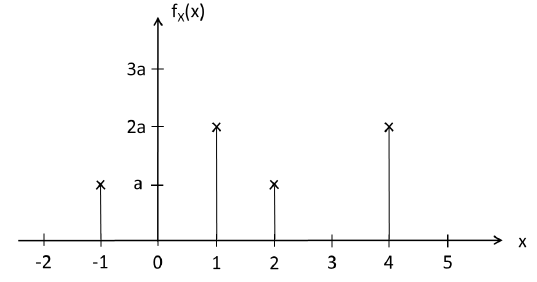

## 2.1 GYLDIG TÆTHEDSFUNKTION

For at bestemme $a$ så $f_x \left(x\right)$er en gyldig tæthedsfunktionen anvendes, at


$$\sum_{i=1}^n f_x \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


syms a
fx = a+2*a+a+2*a == 1;

solve(fx, a)

$$ans = \frac{1}{6}$$

Dette betyder, at $f_x \left(x\right)$er en gyldig tæthedsfunktion for $a=\frac{1}{6}$.

## 2.2  FORDELINGSFUNKTION

For at bestemme fordelingsfunktionen anvendes, at


$$F_x \left(x\right)=\sum_{x_i \le x}^n f_x \left(x_i \right)$$


Hvilket dermed giver, at 


$$F_x \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<-1\\
a & -1\le x<1\\
3a & 1\le x<2\\
4a & 2\le x<4\\
6a & x\ge 4
\end{array}\right\rbrack \right\rbrace$$


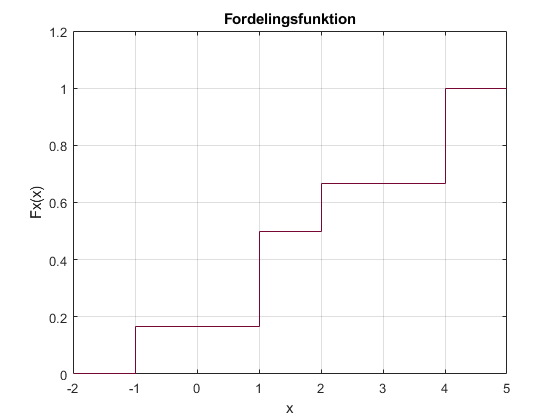

a = 1/6;

X = [-2, -1, 0, 1, 2, 3, 4, 5];
P = [0, a, 0, 2*a, a, 0, 2*a, 0];
Pcdf = [0, 0, 0, 0, 0, 0, 0, 0];

for n = 1:length(P)
    Pcdf(n) = sum(P(1:n));
end

figure(1)
stairs(X, Pcdf, 'Color', Color.DeepCleret);
grid on
title('Fordelingsfunktion')
ylabel('Fx(x)')
xlabel('x')
xlim([-2.00 5.00])
ylim([0.000 1.2])

## 2.3 MIDDELVÆRDI

For at finde middelværdien anvendes, at


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


ExpectationValue = 0;

for n = 1:length(P)
    ExpectationValue = ExpectationValue + (X(n)*P(n));
end

ExpectationValue

ExpectationValue = 1.8333

Middelværdien er dermed bestemt til at være 1.8333.

## 2.4 VARIANS

For at finde variansen anvendes, at


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


ExpectationValueSquare = 0;

for n = 1:length(P)
    ExpectationValueSquare = ExpectationValueSquare + (X(n)^2 * P(n));
end

Variance = ExpectationValueSquare - ExpectationValue^2

Variance = 3.1389

Variansen er dermed bestemt til at være 3.1389.

# **3 STOKASTISKE PROCESSER**

En diskret stokastisk process $X\left\lbrack n\right\rbrack$er givet ved


$$X\left\lbrack n\right\rbrack =2\cdot Y\left\lbrack n\right\rbrack +W$$


Hvor 


$$Y\left\lbrack n\right\rbrack \sim N\left(5,\;2\right)$$


Samt


$$W\sim U\left(-2,\;2\right)$$


Som er kontinuært uniform fordelt. Det antages, at $Y$ og $W$er uafhængige.

## 3.1 REALISERING

Realiseringen er lavet i matlab.

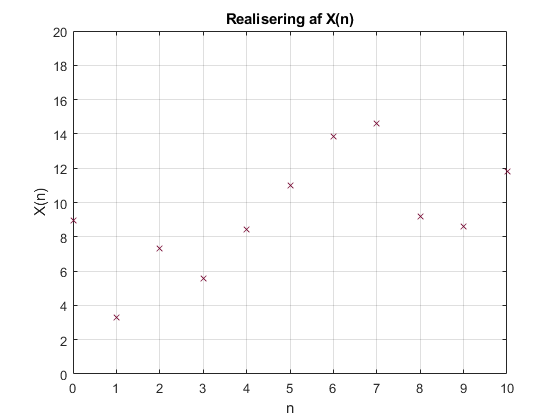

Y = sqrt(2) * randn(1, 11) + 5;
W = 2 * rand - 2;
X = 2 * Y + W;

n = linspace(0, 10, 11);

figure(2)
plot(n, X, 'x', 'Color', Color.DeepCleret);
grid on
title('Realisering af X(n)')
axis([0, 10, 0, 20])
ylabel('X(n)')
xlabel('n')

## 3.2 ENSEMBLE

For at bestemme middelværdien anvendes, at


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack 2\cdot Y+W\right\rbrack$$



$$E\left\lbrack X\left(n\right)\right\rbrack =2\cdot E\left\lbrack Y\right\rbrack +E\left\lbrack W\right\rbrack$$


hvor 

$E\left\lbrack W\right\rbrack =\mu =\frac{a+b}{2}$, $\;\;U\left(a,b\right)$


$$E\left\lbrack W\right\rbrack =\frac{-2+2}{2}=0$$


Samt


$$E\left\lbrack Y\right\rbrack =5,\;\;N\left(5,2\right)$$


Dermed kan det bestemmes at middelværdien er som følgende


$$E\left\lbrack X\right\rbrack =2\cdot 5+0=10$$


For at bestemme variansen anvendes, at


$$\mathrm{Var}\left\lbrack \mathrm{aX}+b\right\rbrack =a^2 \cdot \mathrm{Var}\left(X\right)$$


Hvormed der i dette tilfælde gælder, at 


$$\mathrm{Var}\left\lbrack X\right\rbrack =\mathrm{Var}\left\lbrack 2\cdot Y+W\right\rbrack$$



$$\mathrm{Var}\left\lbrack X\right\rbrack =\mathrm{Var}\left\lbrack 2\cdot Y\right\rbrack +\mathrm{Var}\left\lbrack W\right\rbrack$$



$$\mathrm{Var}\left\lbrack X\right\rbrack =2^2 \cdot \mathrm{Var}\left\lbrack Y\right\rbrack +\mathrm{Var}\left\lbrack W\right\rbrack$$


hvor variansen til $Y$findes ved normalfordelingen som er opgivet og bestemt til 2 og variansen for $W$bestemmes for en uniform fordeling ved følgende udtryk.


$$\mathrm{Var}\left\lbrack W\right\rbrack =\sigma^2 =\frac{1}{12}{\left(b-a\right)}^2$$


EnsembleVariance = 2^2 * 2 + (1/12 * (2 - (-2))^2)

EnsembleVariance = 9.3333

Variansen er dermed bestemt til at være 9.3333.

## 3.3 PROCESSEN

Processen er stationær i den bredde forstand da middelværdien og variansen er konstant og uafhængig af tid. Da $W$er forskellig for de enkelte realisationer er processen ikke ergodisk.

# **4 STATISTIK**

Test af software for en virksomhed viser følgende resultater for det gamle software og det nye. Tiden er angivet i sekunder.

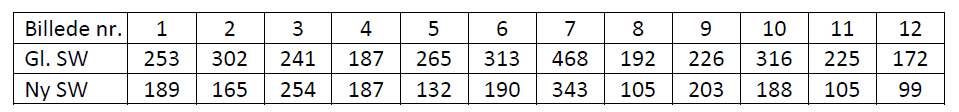

## **4.1 ESTIMERET FORBEDRING**

For at finde den estimeret forbedring tages differencen mellem gammel og ny værdi og gennemsnittet af dette. Det gøres ved, at anvende følgende udtryk.


$$\delta^ˆ =\overline{d} =\frac{1}{n}\sum_{i=1}^n \left(X_{1i} -X_2 \right)$$


measurements = 12;
OldData = [253, 302, 241, 187, 265, 313, 468, 192, 226, 316, 225, 172];
NewData = [189, 165, 254, 187, 132, 190, 343, 105, 203, 188, 105, 99];

Delta = 1 / measurements * sum(OldData - NewData)

Delta = 83.3333

Den estimeret forbedring er bestemt til at være 83.3333 sekunder.

## 4.2 STATISTIK TEST

Der bør anvendes en parret t-test som oftest anvendes til at teste på data fra før og efter målinger.

## 4.3 HYPOTESER

Der opstilles en null hypotese hvor den forventede tidsændring er lig med 2 minutter, altså 120 sekunder. Alternativ er den forskellig fra de 120 sekunder.

$H_0 :$ forventet tidsændring $\left(\delta \right)=120$

$H_1 :$ forventet tidsændring $\left(\delta \right)\not= 120$

## 4.4 SAMPLE VARIANS

For at bestemme sample variansen anvendes, at


$$s_d^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(d_i -\bar{d} \right)}^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(X_{1i} -X_{2i} -\bar{d} \right)}^2$$


SampleVariance = (1 / (measurements - 1)) * ...
    sum(((OldData - NewData) - Delta).^2)

SampleVariance = 2.9413e+03

Sample variansen er dermed bestemt til at være 2941.3.

## 4.5 P-VÆRDIEN

For at bestemme p værdien anvendes, at


$$p=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n-1\right)\right)$$


hvor 


$$t=\frac{\overline{d} -\delta }{\frac{s_d }{\sqrt{n}}}$$


t = (Delta - 120) / (sqrt(SampleVariance) / sqrt(measurements));

PValue = 2 * (1 - tcdf(abs(t), measurements -1))

PValue = 0.0390

P værdien er dermed bestemt til at være 0.039. 

## 4.6 KONFIDENSINTERVALLET

For at bestemme konfidensintervallet anvendes, at


$$\delta_{\pm } =\bar{d} \pm t_0 \cdot \frac{s_d }{\sqrt{n}}$$


TZero = tinv(0.975, measurements - 1);

Confidens.Min = Delta - TZero * (sqrt(SampleVariance) / sqrt(measurements));
Confidens.Max = Delta + TZero * (sqrt(SampleVariance) / sqrt(measurements));

Confidens

Confidens = struct with fields:
    Min: 48.8747
    Max: 117.7920


Dermed er konfidensintervallet bestemt til at være [48.8747; 117.7920].

## 4.7 SIGNIFIKANSNIVEAU

Da p værdien er under et 5% signifikansniveau vist som følgende


$$p<0\ldotp 05$$


må antagelsen om en forbedring på 2 minutter forkastes.